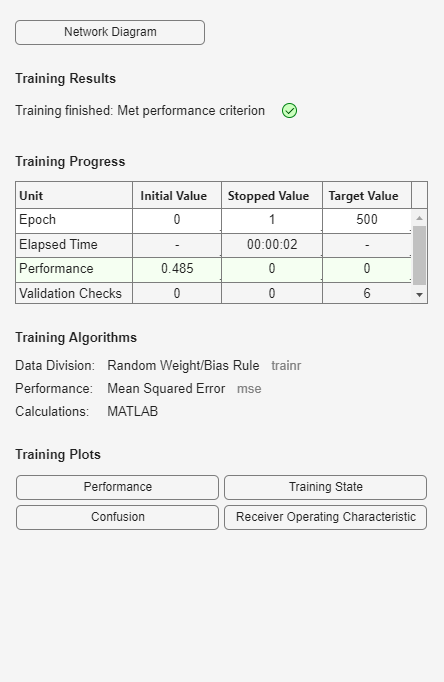

%基于LVQ网络的国家三类型判别（5个神经元）
clear                                       %清理内存
UNDP3                                       %将work文件夹的数据导入内存
X=[C1;C2;C3;S];                             %全部变量合并为一个矩阵
n=length([C1;C2;C3]);                       %训练样本长度
m=length(S);                                %待判样本长度
A=mean(X);                                  %计算全部变量的均值
Mt=A(ones(n,1),:);                          %均值向量平移为矩阵
Ms=A(ones(m,1),:);                          %均值向量平移为矩阵
P=([C1;C2;C3]./Mt)';                        %将三个子样本的数据合并为训练样本
Tc=[ones(length(C1),1)
   2*ones(length(C2),1)
   3*ones(length(C3),1)]';                  %定义一个顺序变量表示的目标输出
T=ind2vec(Tc);                              %输出初始分类
net=newlvq(minmax(P),5,[0.3 0.5 0.2], 0.05,'learnlv2');         
                                            %创建学习向量量化网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %训练网络

Y=sim(net,P)                                %仿真结果

Y =      1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1


Yc=vec2ind(Y)                               %模拟的分类向量

Yc =      1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     3     3     3     3


P_test=(S./Ms)';                            %待判样品信号
y_test=sim(net,P_test);                     %待判样品测试
yc_test=vec2ind(y_test)                     %待判样品的分类结果

yc_test =      1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     3     2     3
